# Part 4: Problem set 

[Return to introduction](matlab: edit S1_Introduction.mlx)

For this problem set, we will consider a different cancer dataset. This one has information about 699 samples of breast tissue (with variables such as cell shape and size, and if the cells are "clumpy"). The target array has information about whether the tissue is cancerous or not (malignant or benign). This dataset also ships with MATLAB®, and is also from the [UCI Machine Learning Repository](http://archive.ics.uci.edu/) [1]. 

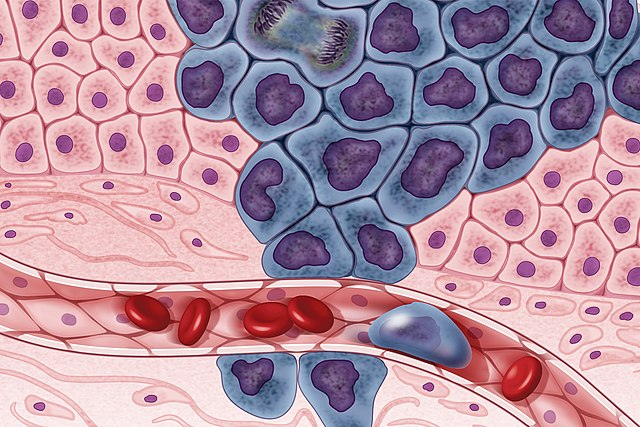

An [illustration](https://commons.wikimedia.org/wiki/File:Cancer_cells_illustration_(40379829875).jpg) of cancer cells (blue) encroaching on normal tissue (pink). 

The cancer cells are a different shape and size than the cells in the healthy tissue, so this kind of information can help us diagnose cancer given a [biopsy](https://en.wikipedia.org/wiki/Biopsy) of such tissue.

First, let's load and set up the data: 

load cancer_dataset.mat % Load
cancerInputs = cancerInputs'; % Reshape
cancerTargets = cancerTargets';

Much like before, if the value of `cancerYN` is 1, the patient has cancer, and if the value is 0, the patient does not. 

cancerYN = cancerTargets(:,2); 

We'll also create table for importing everything into the learning apps, but you won't need to use this table until the supervised learning portion of the exercise: 

cancerTable = [cancerInputs, cancerYN]; % set up a table for the classification learner app

## Problem 1: 

**Clustering the data [no supervision]**

Because we want to know if `cancerInputs` predicts cancer cells in the biopsy sample or not, let's use k-means clustering to cluster the data into ***two*** groups.

**A: **Use `kmeans()` to create a variable called `grps` that clusters the data into two groups.

**B:** Use PCA to reduce the dimensions of your data. Make sure to output a variable for principal components (position 1), scores (position 2), and the explained variance of each PC (position 5). 

**C:** Make a pareto chart to visualize how much variance is explained by each princpal component. Include an x and y label.

 How many PCs do you need to explain most of the variance (how many to explain 80% of the variance? 90%?)? 

**D:**  Plot the transformed data (use the scores) along the first two principal components. Use the `gscatter()` function to color the data by what cluster each data point was placed in. Include an x and y-axis label! 

**E: **Let's figure out how well the clusters from our k-means clustering correspond to whether or not the patient has cancer. 

First, we will make `cancerYN` a categorical array: 

cancerYN = categorical(cancerYN);

Use the `crosstab()` function to figure out how well the clusters correspond to categories/diagnosis (`cancerYN`):

**F: **Plot the heatmap of this cross-tabulation. 

 How did your k-means clustering algorithm do? 

## Problem 2: 

**Make a classification model to predict if a tumor is malignant or benign [supervised learning]**

**A: **Open up the Classification Learner app. Start a new session with `cancerTable` as the dataset and column 10 (the `cancerYN` array) as the response. You can use as many cross-validation folds as you like (I used 5). Make sure to set aside some data for testing. Start the session. 

**B:** Train and test whatever models you like. Starting with training a bunch (e.g. all quick to train) often helps. There's a lot of data here, so this might take a minute. 

**C: **Which model works the best? 

**D: **Make a new model draft (whichever model type you like or think is working the best. You can also do a group of models as a draft, such as **All KNNs**). Since this is a cancer dataset, adjust the cost of incorrectly identifying cancerous tissue as benign.

If you want, play around with refining the features you use to predict if the tumor is malignant or not (feature selection and/or transformation). 

**E: **Train and test this new model. How is it performing in both the validation and testing stages? 

**F:** Export your model to the workspace!

If you were working in a clinic collecting samples of potentially cancerous breast tissue, you could imagine feeding that new data into your model and being able to predict whether or not that tissue is likely to be malignant, and whether further steps need to be taken to ensure the patient's health. 

## References 

[1] Murphy,P.M., Aha, D.W. (1994). UCI Repository of machine learning databases [http://www.ics.uci.edu/~mlearn/MLRepository.html]. Irvine, CA: University of California,  Department of Information and Computer Science.

[Return to introduction](matlab: edit S1_Introduction.mlx)